# Optimal DC Motor Control 

`In this project a simple DC Motor and converter model is derived. The motor is controlled with the converter duty cycle. The goal is to force the motor shaft speed to follow a reference signal. The DC motor model is a state-space model with two states and a linear function representing the converter as control input.`

`DC motor state-space model, continuous`


$$\begin{array}{l}
\dot{x} =\left\lbrack \begin{array}{c}
\ddot{\;\theta } \;\\
\dot{i} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-\frac{b}{J} & \frac{K}{J}\\
-\frac{K}{L} & -\frac{R}{L}
\end{array}\right\rbrack \;\left\lbrack \begin{array}{c}
\dot{\;\theta } \;\\
i
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
\frac{1}{L}
\end{array}\right\rbrack \;u\\
y=\dot{\theta} =\left\lbrack 1\;\;0\right\rbrack \;\left\lbrack \begin{array}{c}
\dot{\theta} \\
i
\end{array}\right\rbrack ,\textrm{where}
\end{array}$$
  


$$\begin{array}{l}
\dot{\theta} =\textrm{motor}\;\textrm{shaft}\;\textrm{angular}\;\textrm{velocity},\\
i=\;\textrm{motor}\;\textrm{current},\\
u=V_I D\;,\textrm{control}\;\textrm{signal}\;\textrm{with}\\
\;\;\;\;\;\;\;\;\;\;\;V_I =\textrm{Converter}\;\textrm{input}\;\textrm{voltage},\\
\;\;\;\;\;\;\;\;\;\;\;\;D=\textrm{Converter}\;\textrm{duty}\;\textrm{cycle}\\
L=\textrm{motor}\;\textrm{inductance},\\
K=\textrm{motor}\;\textrm{torque}\;\textrm{constant}\;\textrm{and}\;\textrm{electromotive}\;\textrm{constant}\\
R=\textrm{motor}\;\textrm{resistane}
\end{array}$$


`First, the system is discretized and it's step response is plotted. Then LQR performance is tested to see how well the system regulates itself around a set point. Moving deeper into the world of optimal control, an open-loop optimal control problem is simulated. Noise is added to demonstrate open-loop restrictions. Lastly, MPC with a Kalman filter is simulated to show how optimal, filtered feedback control outperforms open-loop.`

`RUN ALL SECTIONS IN THE FOLLOWING ORDER TO ENSURE ALL NEEDED VARIABLES ARE SAVED TO WORKSPACE.`

`The scripts might use some variables from a previous script. After running each script once, any script can be run freely.`  

clear variables


## Define System Dynamics

Define parameters and calculate system matrices. Plot some figures.

disp('Define System Dynamics')

Define System Dynamics


L = 0.0900

R = 5.1000

wn = 33.3333

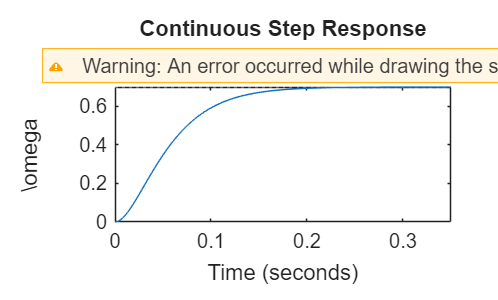

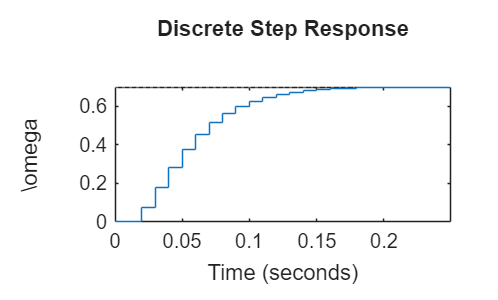

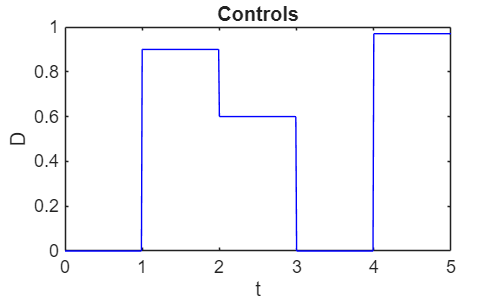

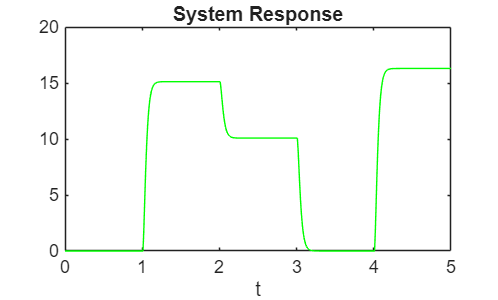

System Step Info:
         RiseTime: 0.0900
    TransientTime: 0.1500
     SettlingTime: 0.1500
      SettlingMin: 0.6474
      SettlingMax: 0.7000
        Overshoot: 0
       Undershoot: 0
             Peak: 0.7000
         PeakTime: 0.6900



run('dcm_sys.m')

## Linear Quadratic Regulator Scheme

Implement LQR and test with 3 different x0-wg combinations (initial state - goal shaft speed). Add some noise to simulate real world behaviour.

disp('Linear Quadratic Regulator Scheme')

Linear Quadratic Regulator Scheme


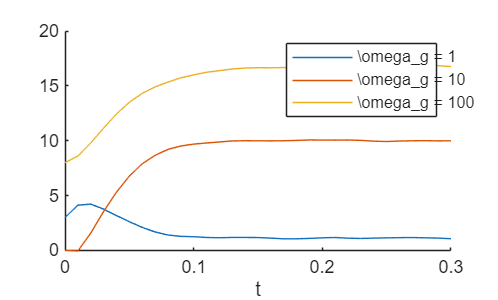

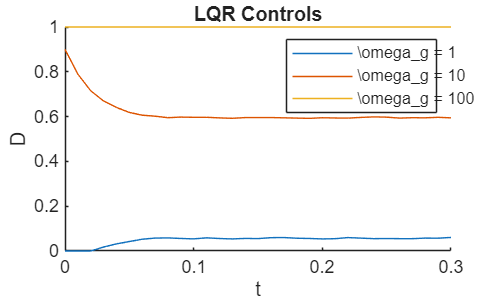

run('dcm_lqr.m')

## Reference Path Following: Open-Loop Optimal Control Problem

Implement an optimal control problem and solve it with qpsol in an open-loop fashion. Force the DC Motor to follow a reference speed signal for timeframe N. Add significant noise to demonstrate how open-loop control doesn't necessarily perform well.

disp('Reference Path following: OCP')

Reference Path following: OCP


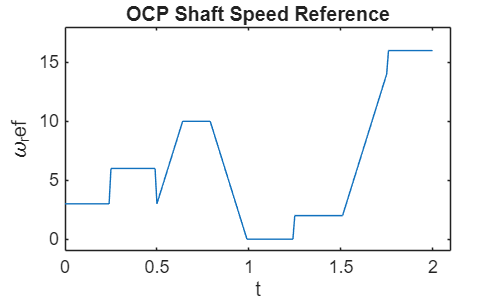


qpOASES -- An Implementation of the Online Active Set Strategy.
Copyright (C) 2007-2015 by Hans Joachim Ferreau, Andreas Potschka,
Christian Kirches et al. All rights reserved.

qpOASES is distributed under the terms of the 
GNU Lesser General Public License 2.1 in the hope that it will be 
useful, but WITHOUT ANY WARRANTY; without even the implied warranty 
of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. 
See the GNU Lesser General Public License for more details.


qpOASES -- An Implementation of the Online Active Set Strategy.
Copyright (C) 2007-2015 by Hans Joachim Ferreau, Andreas Potschka,
Christian Kirches et al. All rights reserved.

qpOASES is distributed under the terms of the 
GNU Lesser General Public License 2.1 in the hope that it will be 
useful, but WITHOUT ANY WARRANTY; without even the implied warranty 
of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. 
See the GNU Lesser General Public License for more details.



####################   qpOASES  --  QP

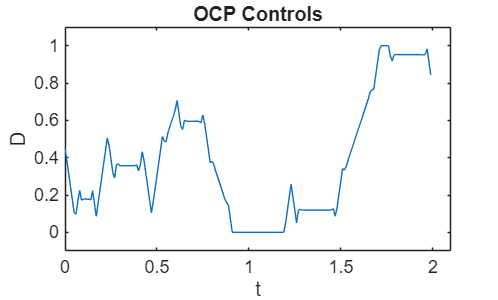

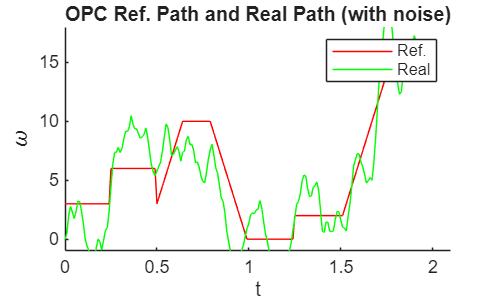

run('dcm_ocp.m')

## Model Predictive Control Scheme

Solve optimal controls in an MPC loop. Add the same kind of noise as in the previous phase to show how feedback loop and Kalman filtering performs significantly better than pure open-loop.

disp('Model Predictive Control Scheme')

Model Predictive Control Scheme



qpOASES -- An Implementation of the Online Active Set Strategy.
Copyright (C) 2007-2015 by Hans Joachim Ferreau, Andreas Potschka,
Christian Kirches et al. All rights reserved.

qpOASES is distributed under the terms of the 
GNU Lesser General Public License 2.1 in the hope that it will be 
useful, but WITHOUT ANY WARRANTY; without even the implied warranty 
of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. 
See the GNU Lesser General Public License for more details.


qpOASES -- An Implementation of the Online Active Set Strategy.
Copyright (C) 2007-2015 by Hans Joachim Ferreau, Andreas Potschka,
Christian Kirches et al. All rights reserved.

qpOASES is distributed under the terms of the 
GNU Lesser General Public License 2.1 in the hope that it will be 
useful, but WITHOUT ANY WARRANTY; without even the implied warranty 
of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. 
See the GNU Lesser General Public License for more details.



####################   qpOASES  --  QP

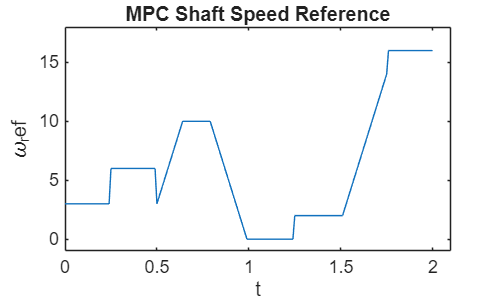

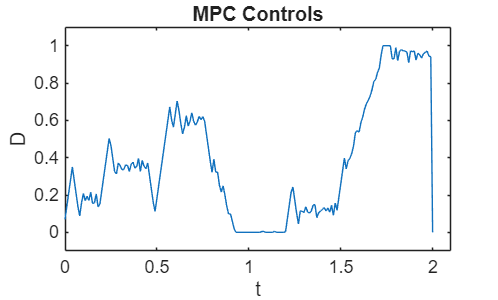

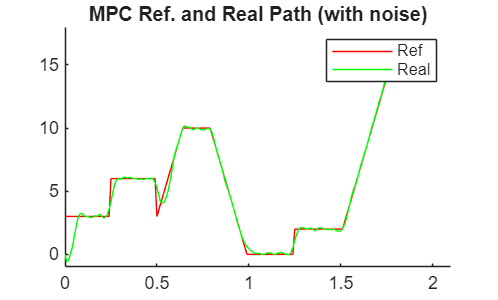

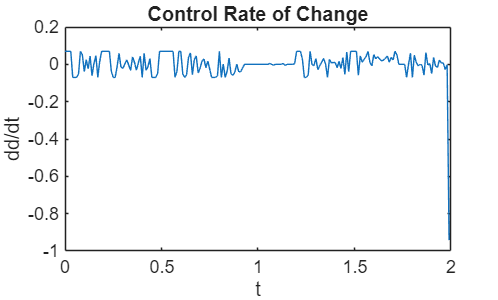

Controls, Max Rate of Change:
    0.0700

max_dd is met


run('dcm_mpc.m')